# Probabilistic roadmap method, Breadth-first search

The following code uses the PRM method to generate random points in the free part of the map, and then join the points to generate the graph.

Then the path from the starting point to the end point is obtained using the BFS algorithm. 

Finally the path is made smoother.

At the end calculates the reference path to be given to the controller in simulink.

clear all; close all; clc;

% Load map from a .mat file
% data = load('test/Files_mat/map_straight_with_roundabout.mat');
data = load('maps_5_1.mat');  % Sostituisci 'nome_file_mappa.mat' con il tuo percorso e nome del file

% Check available fields in 'data' structure
disp(fieldnames(data));

    {'invertedImage'}




% Extract map from data structure
% map = data.map_straight_with_roundabout;
map = data.invertedImage;

Start and goal point coordinates for the maps_5_1

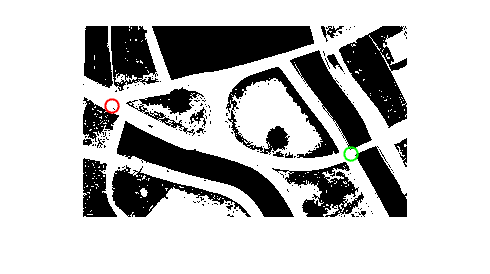

x_start = 30;
y_start = 80;
x_goal = 269;           %215
y_goal = 128;           %185

% Definition of start and goal points
Qs = [x_start, y_start];
Qg = [x_goal, y_goal];

legend_names = {};

% Plot initialization
figure;
imshow(map);
hold on;

% Plotting the start and goal points on the map
plot(Qs(1), Qs(2), 'ro', 'MarkerSize', 10, 'LineWidth', 1.5);        % Start point (red)
plot(Qg(1), Qg(2), 'go', 'MarkerSize', 10, 'LineWidth', 1.5);        % Goal point (green)

Parameters for PRM algorithm

num_nodes = 500;         % Number of sample points
min_dist = 15;           % Minimum distance between sample points
max_dist = 50;           % Maximum distance between sample points

A number of attempts are made to obtain a free smooth path that does not intersect obstacles

path_free = true;
exit_flag = false;
num_attempts = 5;

for i = 1:num_attempts
    
    if path_free
        disp(['Attempt number: ', num2str(i)]);

Generate random sample points on the map

sample_points = generate_random_points(num_nodes, map, min_dist, Qs, Qg);

Construct the PRM graph

adjacency_matrix = build_PRM_graph(sample_points, map, min_dist, max_dist, Qs, Qg);

Find the path using BFS

[parent, current] = find_path_BFS(adjacency_matrix, sample_points, Qs, Qg);

Reconstructs the previously obtained path plotting it

optimal_path = reconstruct_path(parent, current, sample_points);

Interpolate trajectory using cubic polynomial in order to make it smooth

[smooth_path, exit_flag] = cubic_polynomial(optimal_path, sample_points, map);

Check if an obstacle-free path has been found

Attempt number: 1


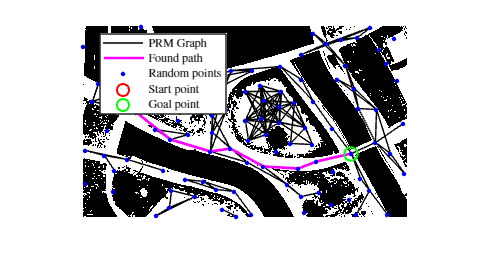

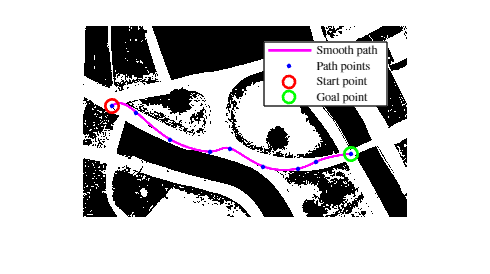

Path intersects with an obstacle!


Attempt number: 2


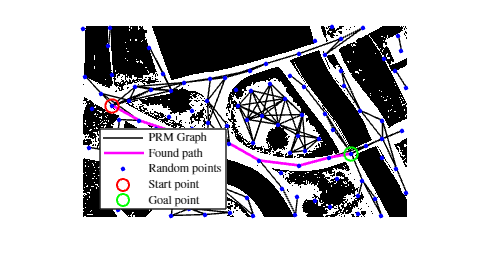

Found obstacle-free path on attempt number: 2


    if exit_flag
        path_free = false;
        disp(['Found obstacle-free path on attempt number: ', num2str(i)]);
    end

    end
    if (i == num_attempts) && path_free
        disp(['No obstacle-free path was found in ', num2str(i), ' attempts!']);
    end
end

From the smooth path it calculates the trajectory to be given input to the controller

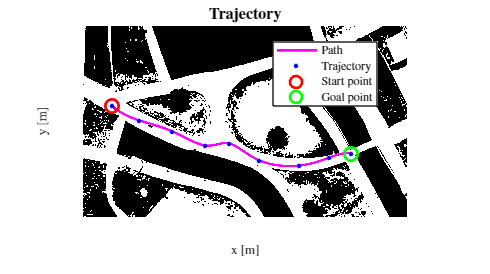

All velocity bounds have been satisfied


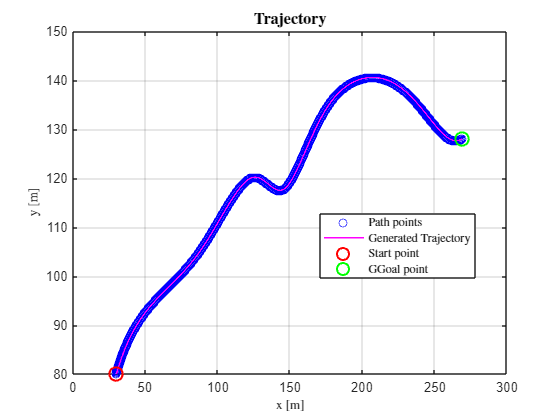

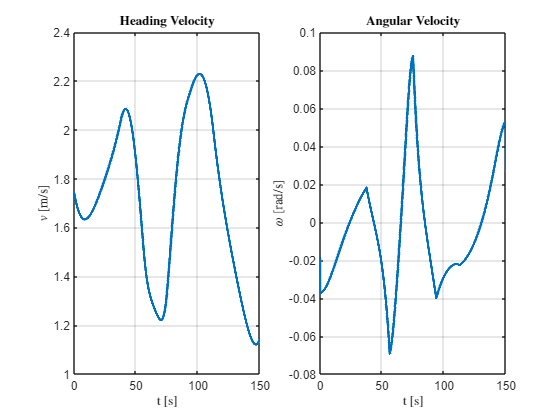

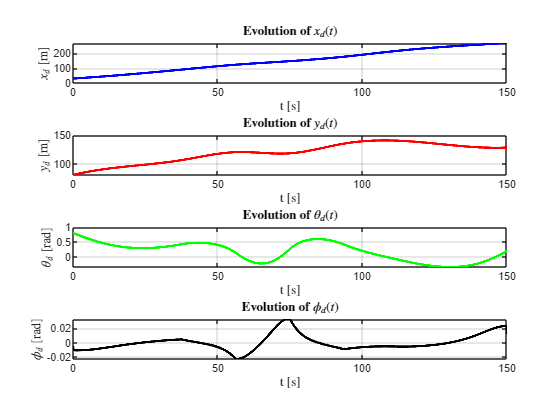

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [10000x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1x1x10000 double]
        DataInfo: 

q0 =    30.0000
   80.0000
    0.7970
   -0.0054


[xd, yd, thetad, phid, q0] = des_trajectory(smooth_path)

## FUNCTIONS

**Generate random sample points on the map**

function points = generate_random_points(num_points, map, min_dist, Qs, Qg)

    % Find all navigable (free) points in the map
    [navigable_Y, navigable_X] = find(map == 1);
    navigable_points = [navigable_X, navigable_Y];
    total_navigable = size(navigable_points, 1);
    
    % Ensure we have enough navigable points
    if total_navigable < num_points
        error('Not enough navigable points to select from');
    end
    
    % Randomly select num_points from navigable points
    selected_indices = randperm(total_navigable, num_points);
    points = navigable_points(selected_indices, :);
    
    % Add start and end points to the list
    points = [Qs; Qg; points];
    
    % Filter points to ensure minimum distance constraint
    valid_points = [];
    for i = 1:num_points
        if isempty(valid_points)
            valid_points = points(i, :);
        else
            % Check distances from the current point to all valid points
            distances = sqrt(sum((valid_points - points(i, :)).^2, 2));
            if all(distances >= min_dist)
                valid_points = [valid_points; points(i, :)];
            end
        end
    end

    points = valid_points;
    
end

**Construct the PRM graph**

function adjacency_matrix = build_PRM_graph(sample_points, map, min_dist, max_dist, Qs, Qg)
    
    legend = 1;
    
    num_points = size(sample_points, 1);
    % % Initialization of the nodes (samples) and adjacency matrix
    adjacency_matrix = zeros(num_points, num_points);
    % plot the generated points in blue
    
    figure;
    imshow(map);
    hold on;

    % Building the roadmap (PRM)
    for i = 3:num_points
        for j = i+1:num_points
            % Check if points i and j are within max_dist
            distance = norm(sample_points(i,:) - sample_points(j,:));
            if (distance <= max_dist && distance >= min_dist)
                % Check if the path between points i and j is obstacle-free
                line_points = round([linspace(sample_points(i,1), sample_points(j,1), 300); linspace(sample_points(i,2), sample_points(j,2), 300)]');
                valid_points = all(line_points >= 1, 2) & line_points(:,1) <= size(map,2) & line_points(:,2) <= size(map,1);
                if all(map(sub2ind(size(map), line_points(valid_points,2), line_points(valid_points,1))) == 1)
                    % If obstacle-free, connect i and j
                    adjacency_matrix(i,j) = 1;
                    adjacency_matrix(j,i) = 1;
                    % Plot the edge between points i and j
                    line([sample_points(i,1), sample_points(j,1)], [sample_points(i,2), sample_points(j,2)], 'Color', 'k', 'HandleVisibility','off');
                    % In order to add to legend 
                    if legend == 1
                        line([sample_points(i,1), sample_points(j,1)], [sample_points(i,2), sample_points(j,2)], 'Color', 'k', 'DisplayName', 'PRM Graph');
                        legend = 0;
                    end
                end
            end
        end
    end
    
    % Ensure start and end points are connected to the roadmap
    for k = [1, 2] % 1 for start, 2 for end
        for j = 3:num_points % Iterate over all other points
            distance = norm(sample_points(k,:) - sample_points(j,:));
            if (distance <= max_dist)
                % Check if the path between points i and j is obstacle-free
                line_points = round([linspace(sample_points(k,1), sample_points(j,1), 300); linspace(sample_points(k,2), sample_points(j,2), 300)]');
                valid_points = all(line_points >= 1, 2) & line_points(:,1) <= size(map,2) & line_points(:,2) <= size(map,1);
                if all(map(sub2ind(size(map), line_points(valid_points,2), line_points(valid_points,1))) == 1)
                    % If obstacle-free, connect i and j
                    adjacency_matrix(k,j) = 1;
                    adjacency_matrix(j,k) = 1;
                    % Plot the edge between points i and j
                    line([sample_points(k,1), sample_points(j,1)], [sample_points(k,2), sample_points(j,2)], 'Color', 'k', 'HandleVisibility','off');
                end
            end
        end
    end
end

**Find the path using BFS**

% Function to find path using BFS
function [parent, current] = find_path_BFS(adjacency_matrix, sample_points, Qs, Qg)
    nodes = sample_points;
    num_samples = size(nodes, 1);

    % Find indices of start and goal nodes in nodes array
    [~, q_start_index] = min(pdist2(nodes, Qs));
    [~, q_goal_index] = min(pdist2(nodes, Qg));

    % BFS initialization
    queue = q_start_index;              % Start with the index of the start node
    parent = zeros(1, num_samples);
    visited = false(1, num_samples);
    visited(q_start_index) = true;      % Mark start node as visited

    % BFS search
    while ~isempty(queue)
        current = queue(1);
        queue(1) = [];
        
        if current == q_goal_index
            % Reconstruct the path from goal to start
            % Interpolate the path using splines
            % Both are done in the main
            return;
        end
        
        % Explore neighbors (nodes connected to current)
        neighbors = find(adjacency_matrix(current,:) == 1);
        for i = 1:length(neighbors)
            if ~visited(neighbors(i))
                visited(neighbors(i)) = true;
                parent(neighbors(i)) = current;
                queue(end+1) = neighbors(i);
            end
        end
    end
end

**Reconstructs the previously obtained path plotting it**

function path = reconstruct_path(parent, goal, nodes)
    path = [];
    current = goal;
    while current ~= 0
        path = [current, path];
        current = parent(current);
    end
    plot_path(path, nodes, 'm');
    
end

Function to plot the lines between the various nodes

function plot_path(path, nodes, color)
    for i = 1:length(path)-1
        line( [nodes(path(i),1), nodes(path(i+1),1)], [nodes(path(i),2), nodes(path(i+1),2)], 'Color', color, 'LineWidth', 2, 'HandleVisibility','off');
    end
    % In order to add to legend
    line( [nodes(path(i-1),1), nodes(path(i),1)], [nodes(path(i-1),2), nodes(path(i),2)], 'Color', color, 'LineWidth', 2, 'DisplayName', 'Found path');
    plot(nodes(:, 1), nodes(:, 2), 'b.', 'MarkerSize', 10, 'DisplayName', 'Random points');  % Plot the generated points in blu
    plot(nodes(path(1),1), nodes(path(1),2), 'ro', 'MarkerSize', 10, 'LineWidth', 1.5, 'DisplayName', 'Start point');
    plot(nodes(path(end),1), nodes(path(end),2), 'go', 'MarkerSize', 10, 'LineWidth', 1.5, 'DisplayName', 'Goal point');
    leg = legend('show');
    set(leg, 'Interpreter','latex', 'fontsize', 9,'Location', 'best')
end

**Interpolate trajectory using cubic polynomial**

function [smooth_path, exit_flag] = cubic_polynomial(optimal_path, nodes, map)
    path_nodes = nodes(optimal_path, :);
    
    x = path_nodes(:, 1);
    y = path_nodes(:, 2);
    
    % Interpolate using splines
    t = 1:length(x);
    ts = 1:0.001:length(x);  % Smoother interpolation with smaller intervals
    
    % Cubic spline interpolation
    smooth_path(:, 1) = spline(t, x, ts);
    smooth_path(:, 2) = spline(t, y, ts);
    
    % Plot the smooth path
    figure;
    imshow(map);
    hold on;
    plot(smooth_path(:, 1), smooth_path(:, 2), 'm', 'LineWidth', 2);
    plot(x, y, 'b.', 'MarkerSize', 10);  % Original path points
    plot(path_nodes(1, 1), path_nodes(1, 2), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
    plot(path_nodes(end, 1), path_nodes(end, 2), 'go', 'MarkerSize', 10, 'LineWidth', 2);
    % Adding legend
    legend('Smooth path', 'Path points', 'Start point', 'Goal point', 'fontsize', 9, 'Location', 'best', 'Interpreter','latex')
    
    % Check if the smooth path intersects with obstacles
    for i = 1:length(smooth_path)
        x_int = round(smooth_path(i, 1));
        y_int = round(smooth_path(i, 2));
        
        if ~map(y_int, x_int)
            disp('Path intersects with an obstacle!');
            exit_flag = false;
            return
        end
    end
    exit_flag = true;
end


**From the smooth path (geometric path) it determines a timing law over the path to satisfy that following velocity bounds, it calculates theta and phi and create desired trajectory to be given input to the controller **

%% ASCISSA CURVILINEA
% function [xd, yd, thetad, phid, q0] = des_trajectory(smooth_path, map)
% 
%     l = 0.5;    % Set the value of l accordingly
%     tf = 300;   % Final time in seconds
% 
%     % Extract x and y coordinates from smooth_path
%     x = smooth_path(:, 1);
%     y = smooth_path(:, 2);
% 
%     % Compute the arc length s for each point
%     s = zeros(size(x));
%     for i = 2:length(x)
%         s(i) = s(i-1) + sqrt((x(i)-x(i-1))^2 + (y(i)-y(i-1))^2);
%     end
% 
%     % Define time vector
%     t = linspace(0, tf, length(x)); % Normalize time from 0 to tf
% 
%     % Generate a finer time grid for interpolation
%     T = linspace(0, tf, 1000); % Increased number of points for interpolation
% 
%     % Compute interpolated s values using spline interpolation
%     s_t = interp1(t, s, T, 'spline');   % Arc length as a function of time
% 
%     % Interpolate x and y values using spline interpolation based on s_t
%     x_t = interp1(s, x, s_t, 'spline');
%     y_t = interp1(s, y, s_t, 'spline');
% 
%     % Compute derivatives
%     x_dot = gradient(x_t, T);
%     y_dot = gradient(y_t, T);
%     x_ddot = gradient(x_dot, T);
%     y_ddot = gradient(y_dot, T);
% 
%     % Compute theta, phi, v, and omega
%     theta = atan2(y_dot/(sqrt(x_dot.^2 + y_dot.^2)), x_dot/(sqrt(x_dot.^2 + y_dot.^2)));
%     phi = atan(l * (y_ddot .* x_dot - x_ddot .* y_dot) ./ (x_dot.^2 + y_dot.^2));
%     v = sqrt(x_dot.^2 + y_dot.^2);
%     omega = (y_ddot .* x_dot - x_ddot .* y_dot) ./ (x_dot.^2 + y_dot.^2);
% 
%     % ds = gradient(s_t,T);
%     % v=v.*ds;
%     % omega=omega.*ds;
% 
%     v_max = 5;  % Velocity limit
%     omega_max = 1;  % Angular velocity limit
% 
%     if (max(abs(v)) <= v_max && max(abs(omega)) <= omega_max)
%         disp('All velocity bounds have been satisfied');
%     else
%         disp('Not all velocity bounds have been satisfied');
%     end
% 
%     xd = timeseries(x_t, T);
%     yd = timeseries(y_t, T);
%     thetad = timeseries(theta, T);
%     phid = timeseries(phi, T);
% 
%     xd0 = xd.data(1,1,1);
%     yd0 = yd.data(1,1,1);
%     phid0 = thetad.data(1,1,1);
%     thetad0 = phid.data(1,1,1);
% 
%     q0 = [xd0, yd0, phid0, thetad0]';
% 
%     % Path visualization
%     figure;
%     imshow(map);
%     hold on;
%     plot(x, y, 'm', 'lineWidth', 3);
% 
%     % Visualization of the generated trajectory
%     plot(x_t, y_t, 'b', 'lineWidth', 0.8);
%     plot(x(1), y(1), 'ro', 'MarkerSize', 10, 'LineWidth', 1.5);                          % Start point (red)
%     plot(x(end), y(end), 'go', 'MarkerSize', 10, 'LineWidth', 1.5);                      % Goal point (green)
%     % Adding legend
%     legend('Path', 'Trajectory', 'Start point', 'Goal point', 'fontsize', 9, 'Location', 'best', 'Interpreter','latex');
%     title('\textbf{Trajectory}','fontsize',12,'Interpreter','latex');
%     xlabel('x [m]','Interpreter','latex','fontsize',10);
%     ylabel('y [m]','Interpreter','latex','fontsize',10);
%     grid on;
% 
%     % Heading velocity and angular velocity
%     figure;
%     subplot(1,2,1);
%     plot(T, v, 'LineWidth', 2);
%     title('\textbf{Heading Velocity}','FontSize',10,'Interpreter','latex');
%     xlabel('t [s]','Interpreter','latex','FontSize',10);
%     ylabel('$v$ [m/s]','Interpreter','latex','FontSize',10);
%     grid on;
% 
%     subplot(1,2,2);
%     plot(T, omega, 'LineWidth', 2);
%     title('\textbf{Angular Velocity}','FontSize',10,'Interpreter','latex');
%     xlabel('t [s]','Interpreter','latex','FontSize',10);
%     ylabel('$\omega$ [rad/s]','Interpreter','latex','FontSize',10);
%     grid on;
% 
%     % Create a new figure for the subplots
%     figure;
%     subplot(4,1,1);
%     plot(T, x_t, 'b', 'LineWidth', 2);
%     title('\textbf{Evolution of $x_d(t)$}','FontSize',10,'Interpreter','latex');
%     xlabel('t [s]','Interpreter','latex','FontSize',10);
%     ylabel('$x_d$ [m]','Interpreter','latex','FontSize',10);
%     grid on;
% 
%     subplot(4,1,2);
%     plot(T, y_t, 'r', 'LineWidth', 2);
%     title('\textbf{Evolution of $y_d(t)$}','FontSize',10,'Interpreter','latex');
%     xlabel('t [s]','Interpreter','latex','FontSize',10);
%     ylabel('$y_d$ [m]','Interpreter','latex','FontSize',10);
%     grid on;
% 
%     subplot(4,1,3);
%     plot(T, theta, 'g', 'LineWidth', 2);
%     title('\textbf{Evolution of $\theta_d(t)$}','FontSize',10,'Interpreter','latex');
%     xlabel('t [s]','Interpreter','latex','FontSize',10);
%     ylabel('$\theta_d$ [rad]','Interpreter','latex','FontSize',10);
%     grid on;
% 
%     subplot(4,1,4);
%     plot(T, phi, 'k', 'LineWidth', 2);
%     title('\textbf{Evolution of $\phi_d(t)$}','FontSize',10,'Interpreter','latex');
%     xlabel('t [s]','Interpreter','latex','FontSize',10);
%     ylabel('$\phi_d$ [rad]','Interpreter','latex','FontSize',10);
%     grid on;
% 
% end

% % NON ASCISSA CURVILINEA
% function [xd, yd, thetad, phid, q0] = des_trajectory(smooth_path)
% 
%     l = 0.5;    % Set the value of l accordingly
%     tf = 300;   % Final time in seconds
% 
%     % Extract x and y coordinates from collected_points
%     x = smooth_path(:, 1);
%     y = smooth_path(:, 2);
% 
%     % Define time vector
%     t = linspace(0, tf, length(x)); % Normalize time from 0 to tf
% 
%     % Fit a cubic polynomial to the arc length s as a function of t
%     % Assume s(t) = a0 + a1*t + a2*t^2 + a3*t^3
%     % Here we use polyfit to fit a cubic polynomial to a set of sample s values
%     s_sample = linspace(0, 1, length(t));  % Sample s values
%     p = polyfit(t, s_sample, 3);  % Fit polynomial
% 
%     % Generate a finer time grid for interpolation
%     T = linspace(0, tf, 1000); % Increased number of points for interpolation
% 
%     % Compute interpolated s values using the cubic polynomial
%     s_t = polyval(p, T);
% 
%     % Interpolate x and y values using spline interpolation based on s_t
%     x_t = interp1(s_sample, x, s_t, 'spline');
%     y_t = interp1(s_sample, y, s_t, 'spline');
% 
%     % Compute derivatives
%     x_dot = gradient(x_t, T);
%     y_dot = gradient(y_t, T);
%     x_ddot = gradient(x_dot, T);
%     y_ddot = gradient(y_dot, T);
% 
%     % Compute theta, phi, v, and omega
%     theta = atan2(y_dot, x_dot);
%     phi = atan(l * (y_ddot .* x_dot - x_ddot .* y_dot) ./ (x_dot.^2 + y_dot.^2));
%     v = sqrt(x_dot.^2 + y_dot.^2);
%     omega = (y_ddot .* x_dot - x_ddot .* y_dot) ./ (x_dot.^2 + y_dot.^2);
% 
%     v_max = 5;  % Velocity limit
%     omega_max = 1;  % Angular velocity limit
% 
%     if (max(abs(v)) <= v_max && max(abs(omega)) <= omega_max)
%         disp('All velocity bounds have been satisfied');
%     else
%         disp('Not all velocity bounds have been satisfied');
%     end
% 
%     xd = timeseries(x_t, T);
%     yd = timeseries(y_t, T);
%     thetad = timeseries(theta, T);
%     phid = timeseries(phi, T);
% 
%     xd0 = xd.data(1,1,1);
%     yd0 = yd.data(1,1,1);
%     phid0 = thetad.data(1,1,1);
%     thetad0 = phid.data(1,1,1);
% 
%     q0 = [xd0, yd0, phid0, thetad0]';
% 
%     % Visualization of the generated trajectory
%     plot(x_t, y_t, 'b', 'lineWidth', 0.8);
% 
%     % Adding legend
%     legend('Path', 'Trajectory', 'Start point', 'Goal point', 'fontsize', 9, 'Location', 'best', 'Interpreter','latex');
%     title('\textbf{Trajectory}','fontsize',12,'Interpreter','latex');
%     xlabel('x [m]','Interpreter','latex','fontsize',10);
%     ylabel('y [m]','Interpreter','latex','fontsize',10);
%     grid on;
%     % Visualization of the generated trajectory
%     figure;
%     plot(x, y, 'bo-', 'DisplayName', 'Path points');
%     hold on;
%     plot(x_t, y_t, 'm', 'lineWidth', 1.2, 'DisplayName', 'Generated Trajectory');
%     plot(x(1), y(1), 'ro', 'MarkerSize', 10, 'LineWidth', 1.5, 'DisplayName', 'Start point');            % Start point (red)
%     plot(x(end), y(end), 'go', 'MarkerSize', 10, 'LineWidth', 1.5, 'DisplayName', 'GGoal point');        % Goal point (green)
%     title('\textbf{Trajectory}','fontsize',12,'Interpreter','latex');
%     xlabel('x [m]','Interpreter','latex','fontsize',10);
%     ylabel('y [m]','Interpreter','latex','fontsize',10);
%     legend('Location', 'best', 'Interpreter','latex');
%     grid on;
% 
%     % Heading velocity and angular velocity
%     figure;
%     subplot(1,2,1);
%     plot(T, v, 'LineWidth', 2);
%     title('\textbf{Heading Velocity}','FontSize',10,'Interpreter','latex');
%     xlabel('t [s]','Interpreter','latex','FontSize',10);
%     ylabel('$v$ [m/s]','Interpreter','latex','FontSize',10);
%     grid on;
% 
%     subplot(1,2,2);
%     plot(T, omega, 'LineWidth', 2);
%     title('\textbf{Angular Velocity}','FontSize',10,'Interpreter','latex');
%     xlabel('t [s]','Interpreter','latex','FontSize',10);
%     ylabel('$\omega$ [rad/s]','Interpreter','latex','FontSize',10);
%     grid on;
% 
%     % Create a new figure for the subplots
%     figure;
%     subplot(4,1,1);
%     plot(T, x_t, 'b', 'LineWidth', 2);
%     title('\textbf{Evolution of $x_d(t)$}','FontSize',10,'Interpreter','latex');
%     xlabel('t [s]','Interpreter','latex','FontSize',10);
%     ylabel('$x_d$ [m]','Interpreter','latex','FontSize',10);
%     grid on;
% 
%     subplot(4,1,2);
%     plot(T, y_t, 'r', 'LineWidth', 2);
%     title('\textbf{Evolution of $y_d(t)$}','FontSize',10,'Interpreter','latex');
%     xlabel('t [s]','Interpreter','latex','FontSize',10);
%     ylabel('$y_d$ [m]','Interpreter','latex','FontSize',10);
%     grid on;
% 
%     subplot(4,1,3);
%     plot(T, theta, 'g', 'LineWidth', 2);
%     title('\textbf{Evolution of $\theta_d(t)$}','FontSize',10,'Interpreter','latex');
%     xlabel('t [s]','Interpreter','latex','FontSize',10);
%     ylabel('$\theta_d$ [rad]','Interpreter','latex','FontSize',10);
%     grid on;
% 
%     subplot(4,1,4);
%     plot(T, phi, 'k', 'LineWidth', 2);
%     title('\textbf{Evolution of $\phi_d(t)$}','FontSize',10,'Interpreter','latex');
%     xlabel('t [s]','Interpreter','latex','FontSize',10);
%     ylabel('$\phi_d$ [rad]','Interpreter','latex','FontSize',10);
%     grid on;
% 
% end

function [xd, yd, thetad, phid, q0] = des_trajectory(smooth_path)

    l = 0.5;    % Set the value of l accordingly
    tf = 150;   % Final time in seconds

    % Extract x and y coordinates from collected_points
    x = smooth_path(:, 1);
    y = smooth_path(:, 2);

    % Inverti l'ordine dei punti se necessario
    %y = flipud(y);

    % Define time vector
    t = linspace(0, tf, length(x)); % Normalize time from 0 to tf

    % Fit a cubic polynomial to the arc length s as a function of t
    % Assume s(t) = a0 + a1*t + a2*t^2 + a3*t^3
    % Here we use polyfit to fit a cubic polynomial to a set of sample s values
    s_sample = linspace(0, 1, length(t));  % Sample s values
    p = polyfit(t, s_sample, 100);  % Fit polynomial

    % Generate a finer time grid for interpolation
    T = linspace(0, tf, 10000); % Increased number of points for interpolation

    % Compute interpolated s values using the cubic polynomial
    s_t = polyval(p, T);

    % Interpolate x and y values using spline interpolation based on s_t
    x_t = interp1(s_sample, x, s_t, 'spline');
    y_t = interp1(s_sample, y, s_t, 'spline');

    % Compute derivatives
    x_dot = gradient(x_t, T);
    y_dot = gradient(y_t, T);
    x_ddot = gradient(x_dot, T);
    y_ddot = gradient(y_dot, T);

    % Compute theta, phi, v, and omega
    theta = atan2(y_dot, x_dot);
    v = sqrt(x_dot.^2 + y_dot.^2);
    phi = atan(l * (y_ddot .* x_dot - x_ddot .* y_dot) ./ v.^3);
    omega = (y_ddot .* x_dot - x_ddot .* y_dot) ./ v.^2;

    v_max = 5;  % Velocity limit
    omega_max = 1;  % Angular velocity limit

    if (max(abs(v)) <= v_max && max(abs(omega)) <= omega_max)
        disp('All velocity bounds have been satisfied');
    else
        disp('Not all velocity bounds have been satisfied');
    end

    xd = timeseries(x_t, T);
    yd = timeseries(y_t, T);
    thetad = timeseries(theta, T);
    phid = timeseries(phi, T);

    xd0 = xd.data(1,1,1);
    yd0 = yd.data(1,1,1);
    phid0 = thetad.data(1,1,1);
    thetad0 = phid.data(1,1,1);

    q0 = [xd0, yd0, phid0, thetad0]';

    % Visualization of the generated trajectory
    %plot(x_t, y_t, 'b', 'lineWidth', 0.8);

    % Adding legend
    legend('Path', 'Trajectory', 'Start point', 'Goal point', 'fontsize', 9, 'Location', 'best', 'Interpreter','latex');
    title('\textbf{Trajectory}','fontsize',12,'Interpreter','latex');
    xlabel('x [m]','Interpreter','latex','fontsize',10);
    ylabel('y [m]','Interpreter','latex','fontsize',10);
    grid on;
    % Visualization of the generated trajectory
    figure;
    plot(x, y, 'bo', 'DisplayName', 'Path points');
    hold on;
    plot(x_t, y_t, 'm', 'lineWidth', 1.2, 'DisplayName', 'Generated Trajectory');
    plot(x(1), y(1), 'ro', 'MarkerSize', 10, 'LineWidth', 1.5, 'DisplayName', 'Start point');            % Start point (red)
    plot(x(end), y(end), 'go', 'MarkerSize', 10, 'LineWidth', 1.5, 'DisplayName', 'GGoal point');        % Goal point (green)
    title('\textbf{Trajectory}','fontsize',12,'Interpreter','latex');
    xlabel('x [m]','Interpreter','latex','fontsize',10);
    ylabel('y [m]','Interpreter','latex','fontsize',10);
    legend('Location', 'best', 'Interpreter','latex');
    grid on;

    % Heading velocity and angular velocity
    figure;
    subplot(1,2,1);
    plot(T, v, 'LineWidth', 2);
    title('\textbf{Heading Velocity}','FontSize',10,'Interpreter','latex');
    xlabel('t [s]','Interpreter','latex','FontSize',10);
    ylabel('$v$ [m/s]','Interpreter','latex','FontSize',10);
    grid on;

    subplot(1,2,2);
    plot(T, omega, 'LineWidth', 2);
    title('\textbf{Angular Velocity}','FontSize',10,'Interpreter','latex');
    xlabel('t [s]','Interpreter','latex','FontSize',10);
    ylabel('$\omega$ [rad/s]','Interpreter','latex','FontSize',10);
    grid on;

    % Create a new figure for the subplots
    figure;
    subplot(4,1,1);
    plot(T, x_t, 'b', 'LineWidth', 2);
    title('\textbf{Evolution of $x_d(t)$}','FontSize',10,'Interpreter','latex');
    xlabel('t [s]','Interpreter','latex','FontSize',10);
    ylabel('$x_d$ [m]','Interpreter','latex','FontSize',10);
    grid on;

    subplot(4,1,2);
    plot(T, y_t, 'r', 'LineWidth', 2);
    title('\textbf{Evolution of $y_d(t)$}','FontSize',10,'Interpreter','latex');
    xlabel('t [s]','Interpreter','latex','FontSize',10);
    ylabel('$y_d$ [m]','Interpreter','latex','FontSize',10);
    grid on;

    subplot(4,1,3);
    plot(T, theta, 'g', 'LineWidth', 2);
    title('\textbf{Evolution of $\theta_d(t)$}','FontSize',10,'Interpreter','latex');
    xlabel('t [s]','Interpreter','latex','FontSize',10);
    ylabel('$\theta_d$ [rad]','Interpreter','latex','FontSize',10);
    grid on;

    subplot(4,1,4);
    plot(T, phi, 'k', 'LineWidth', 2);
    title('\textbf{Evolution of $\phi_d(t)$}','FontSize',10,'Interpreter','latex');
    xlabel('t [s]','Interpreter','latex','FontSize',10);
    ylabel('$\phi_d$ [rad]','Interpreter','latex','FontSize',10);
    grid on;

end